# Raman Nath Regime

## Initialization



units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
add_Li = aLi_12*0.6;

totalODTpower = 22.5;
EndODTpower = 0.1;

omegax = 81*pi*2*sqrt(EndODTpower/totalODTpower); % trap frequencies 
omegay = 3040*pi*2*sqrt(EndODTpower/totalODTpower);
omegaz = 3040*pi*2*sqrt(EndODTpower/totalODTpower);

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;

D = Wavelength/2; % Lattice period 0.532 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 

LatticePotential = 500; % lattice depth in unit of recoil energy
V = @(X,Y,Z) 0.5*(X.^2 + (omegay/omegax* Y).^2); % function representing the external potential (must have 3 arguments)


ymax = 25*D/rscale; %  grid boundaries [-xmax,xmax]
xmax = 800*D/rscale; %  grid boundaries [-xmax,xmax]
Nx = 16000; % number of grid points for coordinate grid
Ny = 500;
try
    x = gpuArray.linspace(-xmax,xmax,Nx);
    y = gpuArray.linspace(-ymax,ymax,Ny);
    grid = grid2d(x,y);
catch
    grid = grid2d(xmax,Nx,ymax,Ny); % create a two-dimensional NxN grid object
end

task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)


task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;


## Stationary state calculation

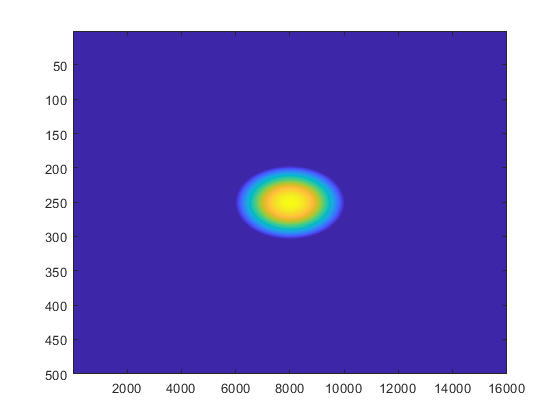


% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);

% Plot the initial state
imagesc(abs(phi).^2)


task.g = 4*pi*add_Li/rscale/sqrt(2*pi/sqrt(omegaz*omegay)*omegax); % nonlinear interaction constant


%% switch on lattice for Deltat
Deltat = 0.4*10^-6/tscale; % total duration for simulation; (20 mico-seconds)
tstep = 1*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

task.init_state = phi;
task.show_image = 0; % show the solution on every precessing step


NmaxP = 2; % maximum mode of momentum to be analyzed

% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)...
    *(cos((pi/D)*X*rscale).^2 + cos((pi/D)*Y*rscale).^2); 
task.UpdatePotential(Vlattice);
% task.history.MomentumDensity = [];
task.user_callback = @(x)task.FFTanalysis2D(true,NmaxP);
steps_ext = task.current_iter + Deltat/tstep/steps_int;


## start simulation

Split-step: iter - 0, mu - 0.000, calc. time - 0.744 sec.; 0 mode Proportion: 1
Split-step: iter - 1, mu - 1356584.407, calc. time - 6.495 sec.; 0 mode Proportion: 0.948
Split-step: iter - 2, mu - 1356584.407, calc. time - 11.536 sec.; 0 mode Proportion: 0.807
Split-step: iter - 3, mu - 1356584.408, calc. time - 16.741 sec.; 0 mode Proportion: 0.612
Split-step: iter - 4, mu - 1356584.411, calc. time - 21.796 sec.; 0 mode Proportion: 0.409
Split-step: iter - 5, mu - 1356584.417, calc. time - 26.789 sec.; 0 mode Proportion: 0.235
Split-step: iter - 6, mu - 1356584.428, calc. time - 31.833 sec.; 0 mode Proportion: 0.112
Split-step: iter - 7, mu - 1356584.446, calc. time - 36.956 sec.; 0 mode Proportion: 0.0418
Split-step: iter - 8, mu - 1356584.472, calc. time - 42.089 sec.; 0 mode Proportion: 0.0105
Split-step: iter - 9, mu - 1356584.510, calc. time - 47.250 sec.; 0 mode Proportion: 0.00123
Split-step: iter - 10, mu - 1356584.559, calc. time - 52.338 sec.; 0 mode Proportion: 1.1e-05
Spli

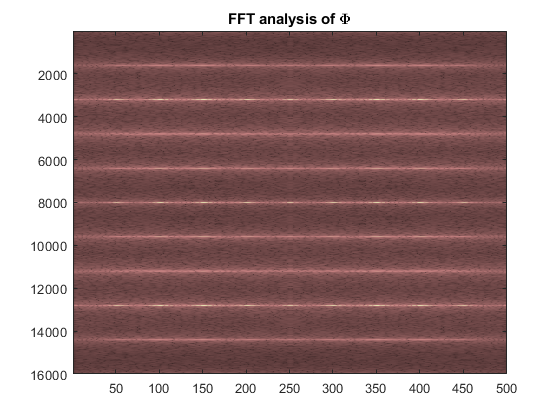

Split-step: iter - 40, mu - 1356597.344, calc. time - 216.624 sec.; 0 mode Proportion: 0.00317



task.solve_split(tstep,steps_int,steps_ext); % run the calculation

## momentum modes distribution

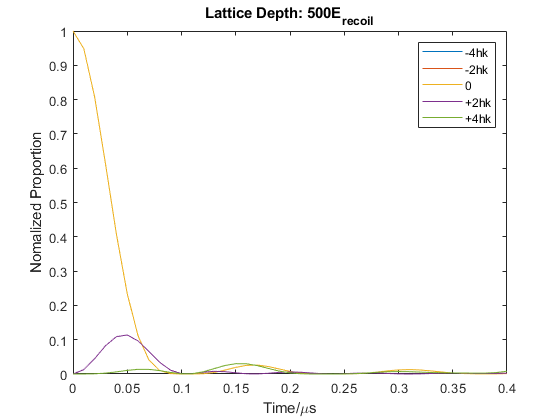


trange = (0:steps_ext)*tstep*steps_int*tscale;
MomentumDensity = Get_momentumDesity_2D( ...
    task.history.MomentumDensity,1:NmaxP*2+1,NmaxP+1);
MomentumDensity = MomentumDensity./max(MomentumDensity(:));
plot(trange*10^6, MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend('-4hk','-2hk','0','+2hk','+4hk')

## Bessel function fit 


Tcoef_theory = LatticePotential*Erecoil/2/hbar

Tcoef_theory = 2.3011e+07

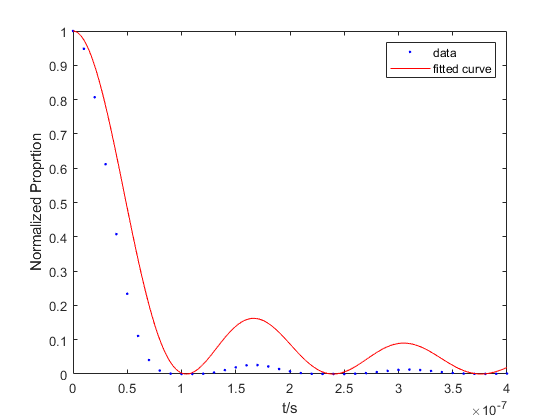

Tcoeffienct = 2.3011e+07

Tcoeffienct = BesselFit(trange,MomentumDensity(:,NmaxP+1)',0,Tcoef_theory)

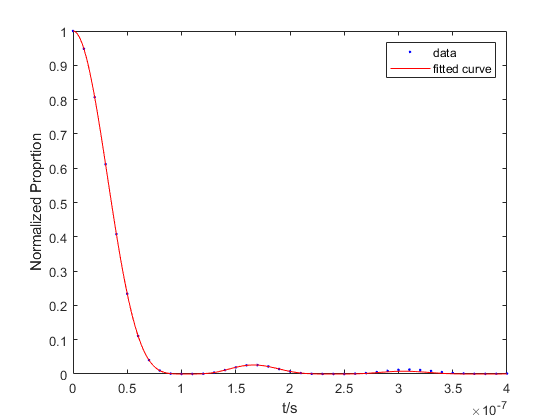

Tcoeffienct = 2.3011e+07


Tcoeffienct = BesselFitSquare(trange,MomentumDensity(:,NmaxP+1)',0,Tcoef_theory)

##  Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 0.8233

function a=  BesselFitSquare(x,FitTarget, order , varargin)
if nargin == 4
    atry = varargin{1};
else 
    atry = 10^5;
end

[m,n]=size(x);
if n>1 
    x = x';
    FitTarget = FitTarget';
end

PlotFigure = 1;
% coefficient = LatticePotential*Erecoil/hbar/2;
ft = fittype(@(a,x)besselj(order,x*a).^4);
f = fit(x,FitTarget,ft,'Start',atry);
if PlotFigure
plot(f,x,FitTarget)
xlabel('t/s')
ylabel('Normalized Proprtion')
end
a = f.a;
end